%the Q set
Q  = readmatrix("data\points.csv");
[Q_hull,area_hull] = convhull(Q);

% the Chebyshev center using definition 1

% x0 = [x;r], x = center, r= radius
x0 = [0;0;0];
target = @(x) x(3);
nonlin_con = builder_constraints(Q)

nonlin_con = function_handle with value:
    @builder_constraints/nonlin_con

lower_bound = ones(3,1)*-inf;
lower_bound(3) = 0;

x_solution = fmincon(target,x0,[],[],[],[],lower_bound,[],nonlin_con)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_solution =    23.0315
   21.8535
   27.8798


center = x_solution(1:2);
r = x_solution(3)

r = 27.8798

fun_circle = @(phi) (center + r*[cos(phi);sin(phi)])

fun_circle = function_handle with value:
    @(phi)(center+r*[cos(phi);sin(phi)])

interval = 0:0.01:pi*2

interval =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


circle = fun_circle(interval)'

circle =    50.9113   21.8535
   50.9099   22.1323
   50.9057   22.4111
   50.8988   22.6898
   50.8890   22.9684
   50.8765   23.2469
   50.8611   23.5253
   50.8430   23.8035
   50.8221   24.0815
   50.7985   24.3593


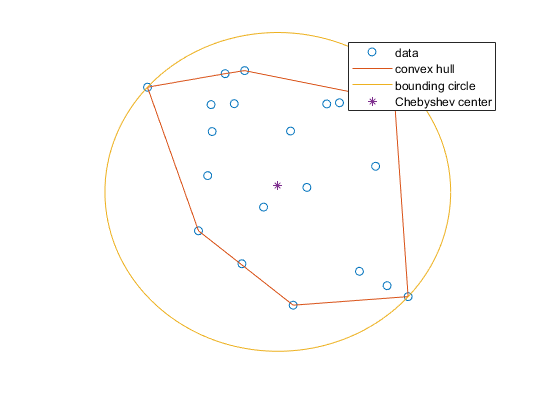

scatter(Q(:,1),Q(:,2))
hold on
plot(Q(Q_hull,1),Q(Q_hull,2))
plot(circle(:,1),circle(:,2))
scatter(center(1),center(1),'*')
legend(["data","convex hull","bounding circle","Chebyshev center"])
set(gca,'visible','off')
saveas(gcf,'../paper/plots/bounding.png')
hold off

% the Chebyshev center solution to the second definition using the second
% definition.


% 1) create a matrix A and vector b that represent the half-spaces that
% intersect in order to create the convexhull returns the list of the points is an ordered fashion
% that compremise the points of the edges of the hull.
% they are going to be used in order to constract the lines 

% 1.1) we will create the a*x <= b by finding a from the line equaltion
% then calculate the correct sign for the inequality by checking the value
% of a random point inside the intersection, and we know that it is non
% empty because of the requirments to make the center

inside_point = sum(Q(Q_hull,:))/numel(Q_hull);
% numel(Q_hull)-1 is the amount of lines drawn in the hull picture above
% (half-spaces) because Q_hull starts and ends at the same point.
A = zeros(numel(Q_hull)-1,2);
b = zeros(numel(Q_hull)-1,1);
k=1;
for i = 1:numel(Q_hull)-1
    p1 = Q(Q_hull(i),:);
    p2 = Q(Q_hull(i+1),:);
    a = [-(p2(2)-p1(2)),p2(1)-p1(1)];
    res = a*(p1');
    if a*(inside_point') >= res
        a = -a;
        res = -res;
    end
    A(k,:) = a;
    b(k) = res;
    k = k + 1;
end

% Ax <= b is ready
% 2) make constraints a_i * x + ||a_i||*r <= b_i
constriants = [A,vecnorm(A,2,2)];
lb = [-inf;-inf;0];
hb = [];
% 3) target function is negative because the algorithm simplex-dual
% minimizes and we need to maximize
c = -[0;0;1];
x_solution = linprog(c,constriants,b,[],[],lb,hb)

Optimal solution found.



x_solution =    25.8030
   24.0037
   16.9113


center1 = x_solution(1:2);
r = x_solution(3)

r = 16.9113

fun_circle = @(phi) (center1 + r*[cos(phi);sin(phi)])

fun_circle = function_handle with value:
    @(phi)(center1+r*[cos(phi);sin(phi)])

interval = 0:0.001:pi*2

interval =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


circle1 = fun_circle(interval)'

circle1 =    42.7142   24.0037
   42.7142   24.0206
   42.7142   24.0375
   42.7141   24.0544
   42.7141   24.0714
   42.7140   24.0883
   42.7139   24.1052
   42.7138   24.1221
   42.7137   24.1390
   42.7135   24.1559


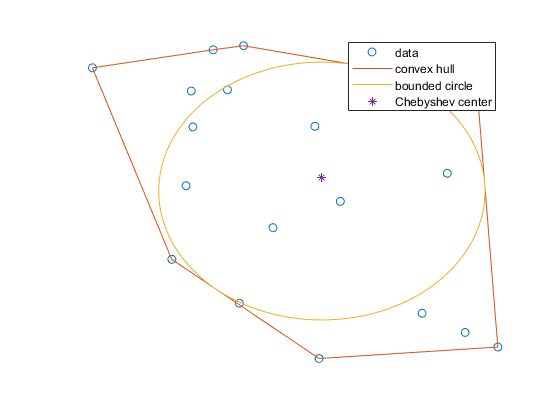

scatter(Q(:,1),Q(:,2))
hold on
plot(Q(Q_hull,1),Q(Q_hull,2))
plot(circle1(:,1),circle1(:,2))
scatter(center1(1),center1(1),'*')
legend(["data","convex hull","bounded circle","Chebyshev center"])
set(gca,'visible','off')
saveas(gcf,'../paper/plots/bounded.png')
hold off

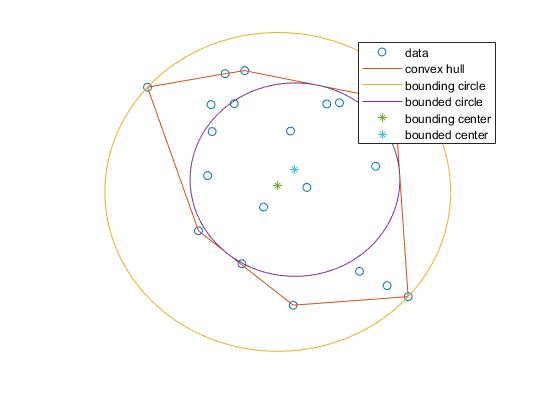

scatter(Q(:,1),Q(:,2))
hold on
plot(Q(Q_hull,1),Q(Q_hull,2))
plot(circle(:,1),circle(:,2))
plot(circle1(:,1),circle1(:,2))
scatter(center(1),center(1),'*')
scatter(center1(1),center1(1),'*')
legend(["data","convex hull","bounding circle","bounded circle","bounding center","bounded center"])
set(gca,'visible','off')
saveas(gcf,'../paper/plots/both.png')
hold off